# 数字图像处理 作业3 (3/18)

阮泉源 201930033629 第三章

## 直方图均衡化

% 读取图片
im_coser = imread('coser.jpg');

im_coser = rgb2gray(im_coser);

L = 256;

    为了显示效果更加显著，首先要将图片进行压扩处理，目的是将灰度级的频数集中在中间区域。所以我们需要将图片归一为0~1之间的数值，然后确定一个函数，有以下几个特性：

- 
$$T\left(1\right)=1$$


- 
$$T\left(0\right)=0$$


- 
$$T\left(0\ldotp 5\right)=0\ldotp 5$$


- 在0~0.5之间为上凸函数

- 在0.5~1之间为下凸函数

    考虑到以上条件，对${{T\left(r\right)=\sum_n \;a}_n r}^n$的一元n次方程，取n=5，假设有$T\prime \left(0\right)=T\prime \left(1\right)=5$，且$T\prime \left(0\ldotp 5\right)=0\ldotp 5$，求解可以得到多项式的系数。

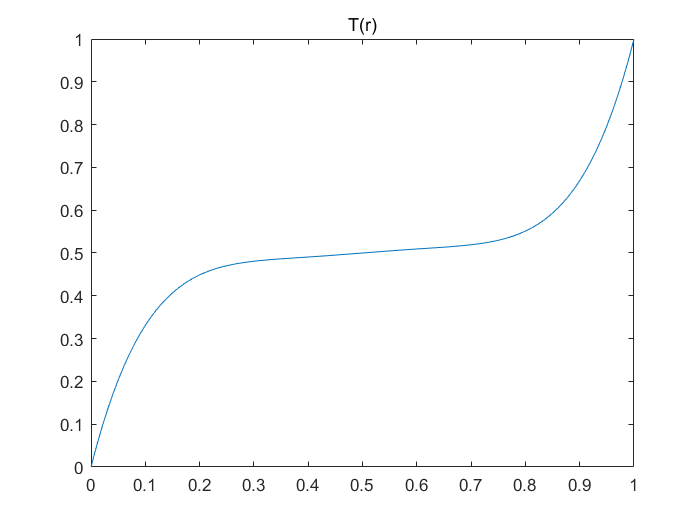

A = [1 1 1 1 1;5 4 3 2 1;
    0.5^5 0.5^4 0.5^3 0.5^2 0.5^1;
    5*0.5^4 4*0.5^3 3*0.5^2 2*0.5^1 1*0.5^0;
    0 0 0 0 1];
B = [1; 5; 0.5; 0.1; 5];
R = A\B;
x = 0:0.01:1;
y = R(1)*x.^5+R(2)*x.^4+R(3)*x.^3+R(4)*x.^2+R(5)*x.^1;
figure;
plot(x,y);
title('T(r)');

    在进行灰度压缩前首先要将灰度值归一化到0~1之间，利用上面得到的函数$T\left(r\right)$进行映射，可以得到灰度级压缩后的图片。

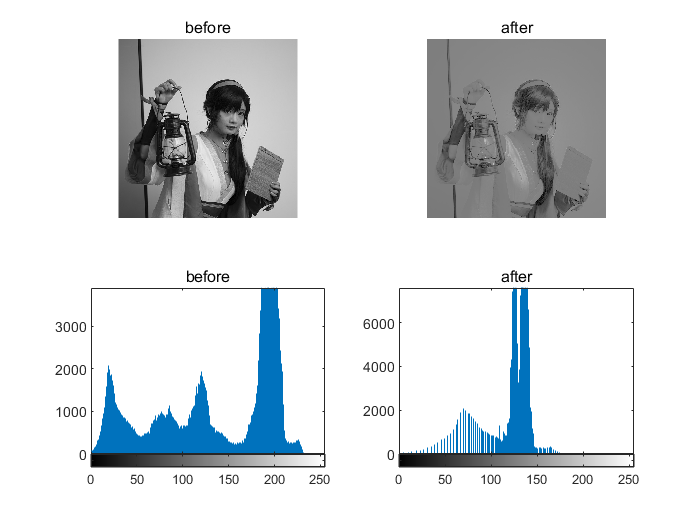

% 灰度压缩
im_coser_norm = double(im_coser)/(L-1);

im_coser_zip = R(1)*im_coser_norm.^5+R(2)*im_coser_norm.^4+R(3)*im_coser_norm.^3+R(4)*im_coser_norm.^2+R(5)*im_coser_norm.^1;

im_coser_zip = uint8(255*im_coser_zip);

figure;
subplot(2,2,1)
imshow(im_coser)
title('before')

subplot(2,2,2)
imshow(im_coser_zip)
title('after')

subplot(2,2,3)
imhist(im_coser)
title('before')

subplot(2,2,4)
imhist(im_coser_zip)
title('after')

    如图所示，可以看到图片变得模糊不清。而灰度级也被压缩到了比较中间的位置。

    接下来需要得到压缩后的直方图。

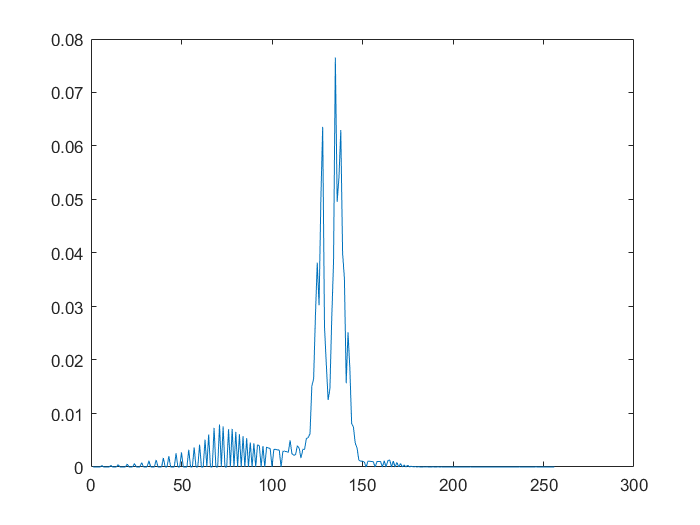

hist_list = zeros(1,L);
for i=1:L
    hist_list(i) = sum(sum(im_coser_zip(:,:)==(i-1)));
end

[w,h] = size(im_coser_zip);
N = w*h;
hist_list = hist_list/N;
figure;
plot(hist_list)

    最后，利用自适应算法恢复图片。

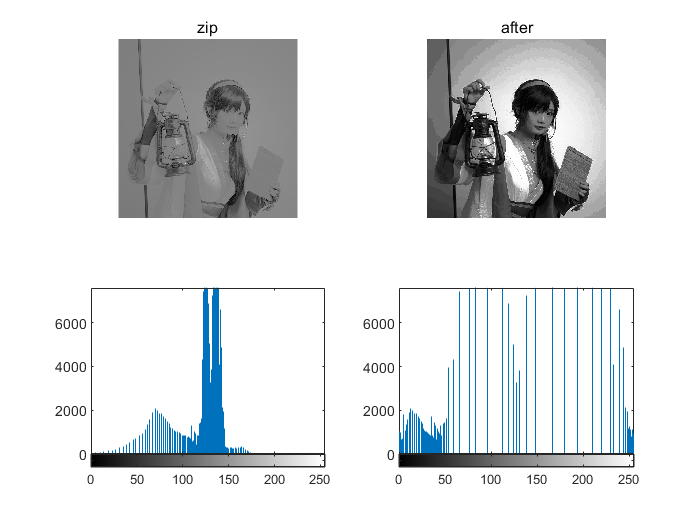

im_out = zeros(w, h);

for i=1:L
    im_out(im_coser_zip==(i-1))=sum(hist_list(1:i));
end

im_out = uint8(round(im_out*(L-1)));

figure;
subplot(2,2,1)
imshow(im_coser_zip)
title('zip')

subplot(2,2,2)
imshow(im_out)
title('after')

subplot(2,2,3)
imhist(im_coser_zip)

subplot(2,2,4)
imhist(im_out)

    可以看到，恢复的图片较压缩后的图片视觉上有着较大的提升。